## Tutorial 1

In this tutorial you will set up your first linear model with BrainStat. To this end, we will load some sample data from the ABIDE dataset. Note that,contrary to the results shown in our manuscript, we are only using a few sites to reduce computation time in this tutorial. As such the results shown here differ from those reported in our manuscript. To get identical results, simply set `sites` to `nan`. 

sites = ["PITT", "OLIN", "OHSU"];
[cortical_thickness, demographics] = fetch_abide_data('sites', sites);
[surf_left, surf_right] = fetch_template_surface('civet41k');

mask = fetch_mask('civet41k');

Lets have a look at the cortical thickness data. To do this, we will use the surface plotter included with BrainSpace. Note that we use a recent version of BrainSpace in this tutorial (released on 16 July, 2021). If you've installed an older version please update before continuing. Lets plot mean thickness.

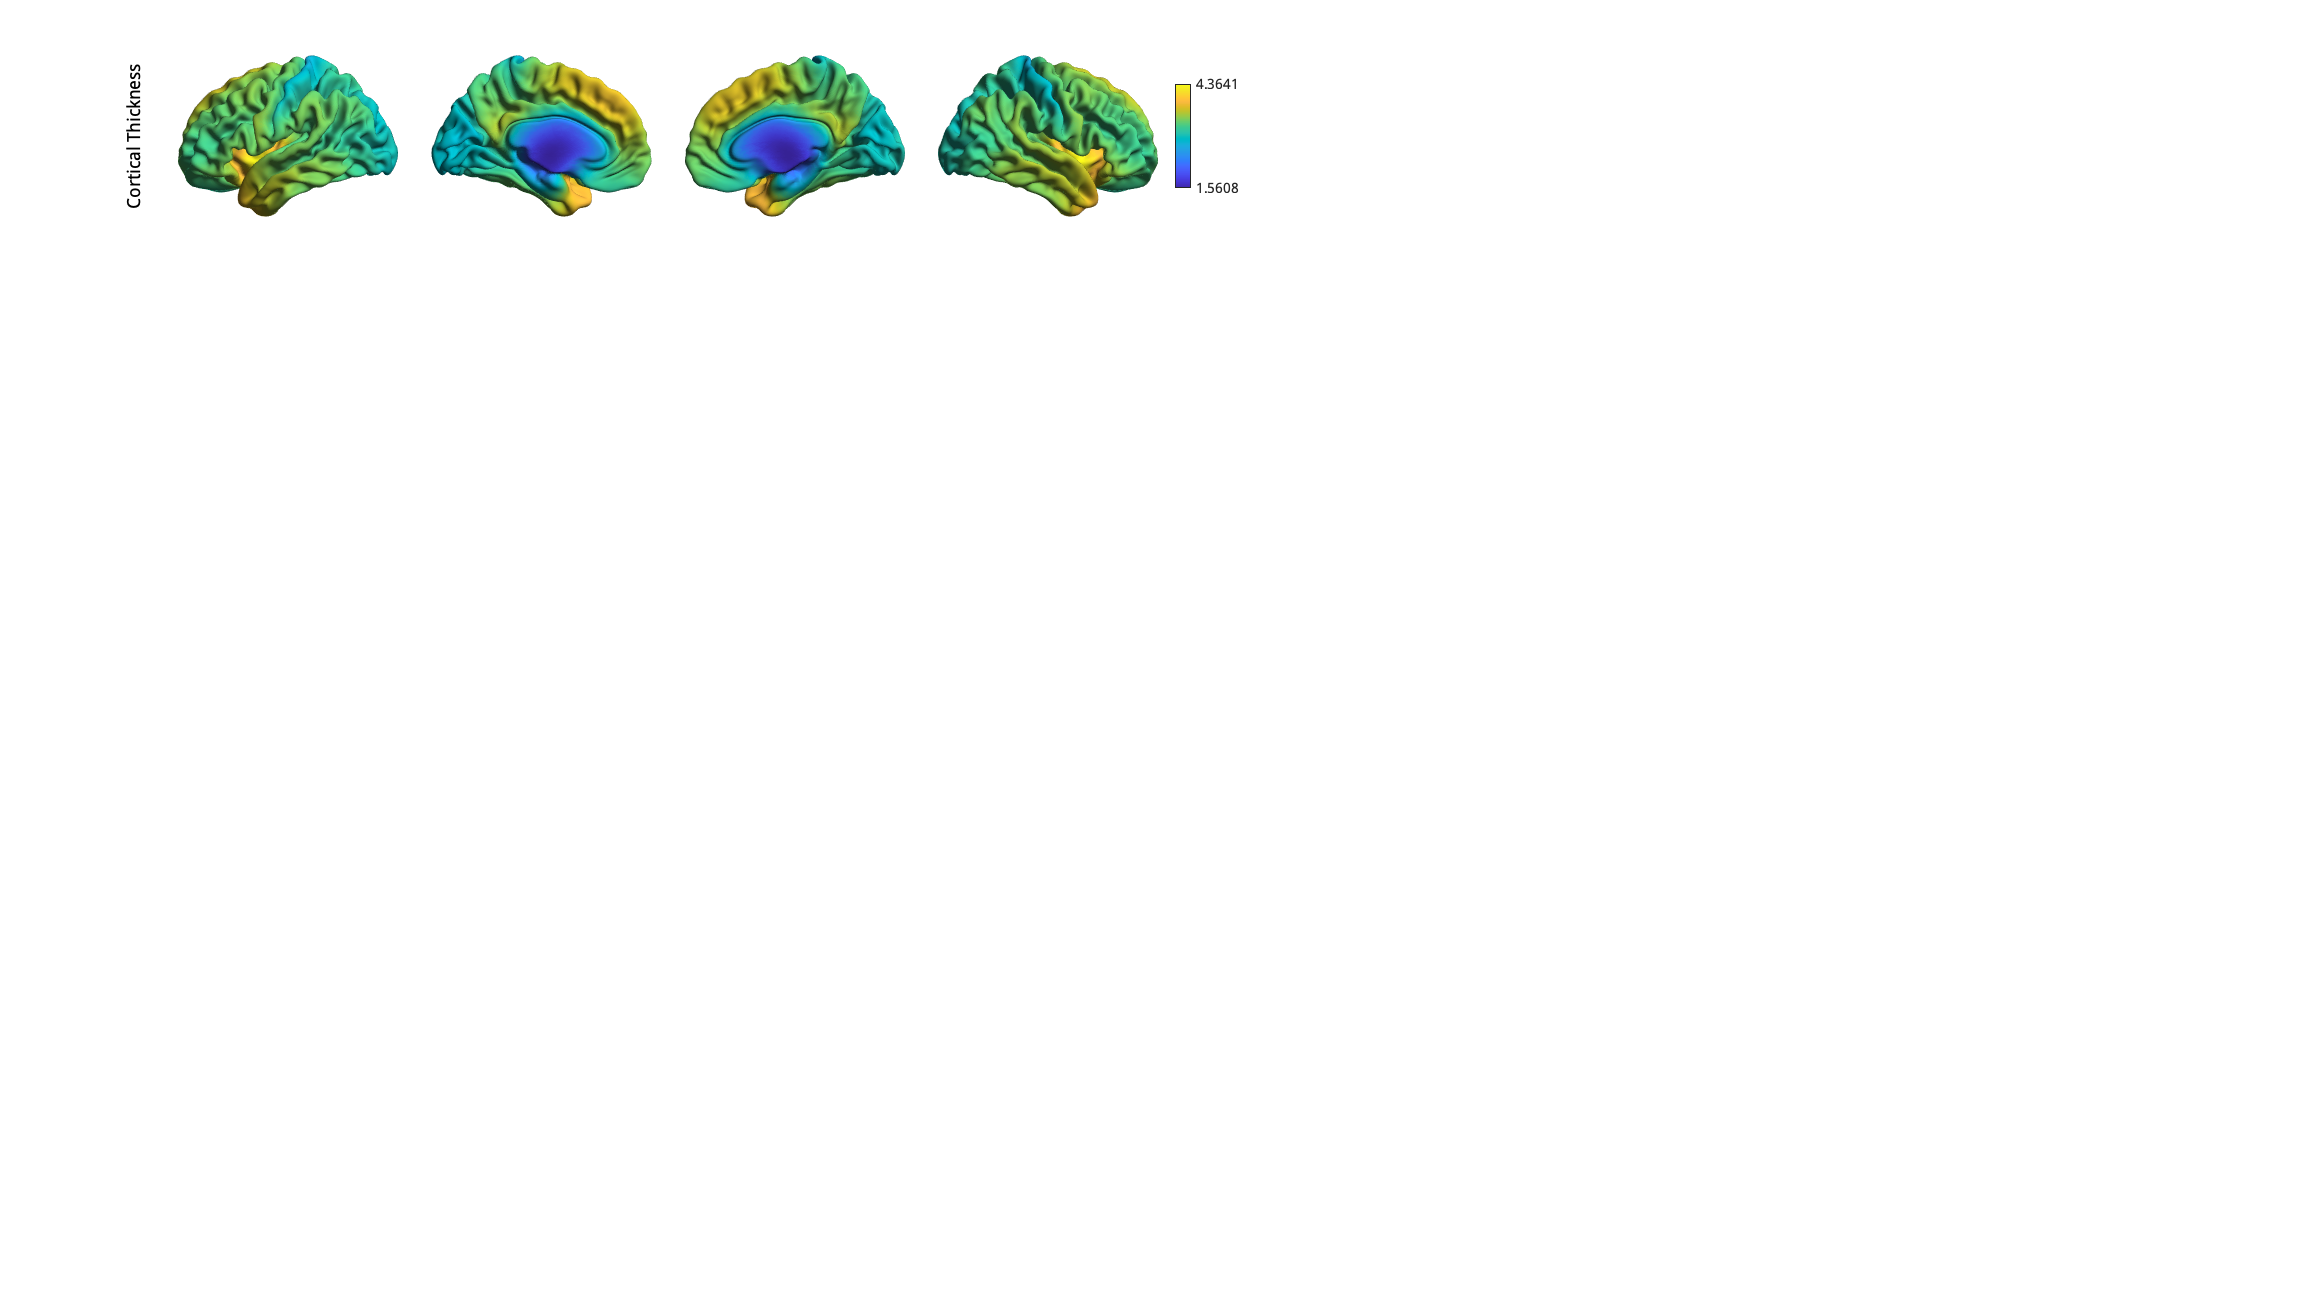

plot_hemispheres(...
    mean(cortical_thickness)',  ...
    {surf_left, surf_right}, ...
    'labeltext', 'Cortical Thickness' ...
);

Next, lets see whether cortical thickness is related to age in our sample data. To this end we can create a linear model with BrainStat. First we declare the behavioral variables as `FixedEffects`. Once, that's done we can create the model by simply adding the terms together. Lets set up a model with age and patient status as fixed effects.

term_age = FixedEffect(demographics.AGE_AT_SCAN, 'Age');
% Subtract 1 from patient groups such that patient == 0, 
% and healthy == 1
term_patient = FixedEffect(demographics.DX_GROUP - 1, 'Healthy');
model = term_age + term_patient;
disp(model)

  116×3 FixedEffect array with properties:

     names: ["Age"    "intercept"    "Healthy"]
    matrix: [116×3 double]



As you can see, model contains two properties: the names of each variable and a matrix containing the effects in a observation-by-variable matrix. 

Beside simple fixed effects, we may also be interested in interaction effects. We can add these to the model by multiplying terms. Lets create a model with an interaction between age and patient status.

model_interaction = 1 + term_age + term_patient + ...
    term_age * term_patient;

Now, imagine we have some cortical marker (e.g. cortical thickness) for each subject, and we want to evaluate whether this marker changes with age whilst correcting for effects of patient status. To do this, we can use the model we defined before, and a contrast in observations (here: age). Then we simply initialize an SLM model and fit it to the cortical thickness data. Note that the fitting may take a few minutes.

contrast_age = demographics.AGE_AT_SCAN;
BrainStatModel = SLM( ...
    model, ...
    contrast_age, ...
    'surf', {surf_left, surf_right}, ...
    'correction', 'rft', ...
    'mask', mask);
BrainStatModel.fit(cortical_thickness);

We can access the outcome of this model through its properties. Lets plot the t-values and the vertexwise p-values derived from a random field theory correction.

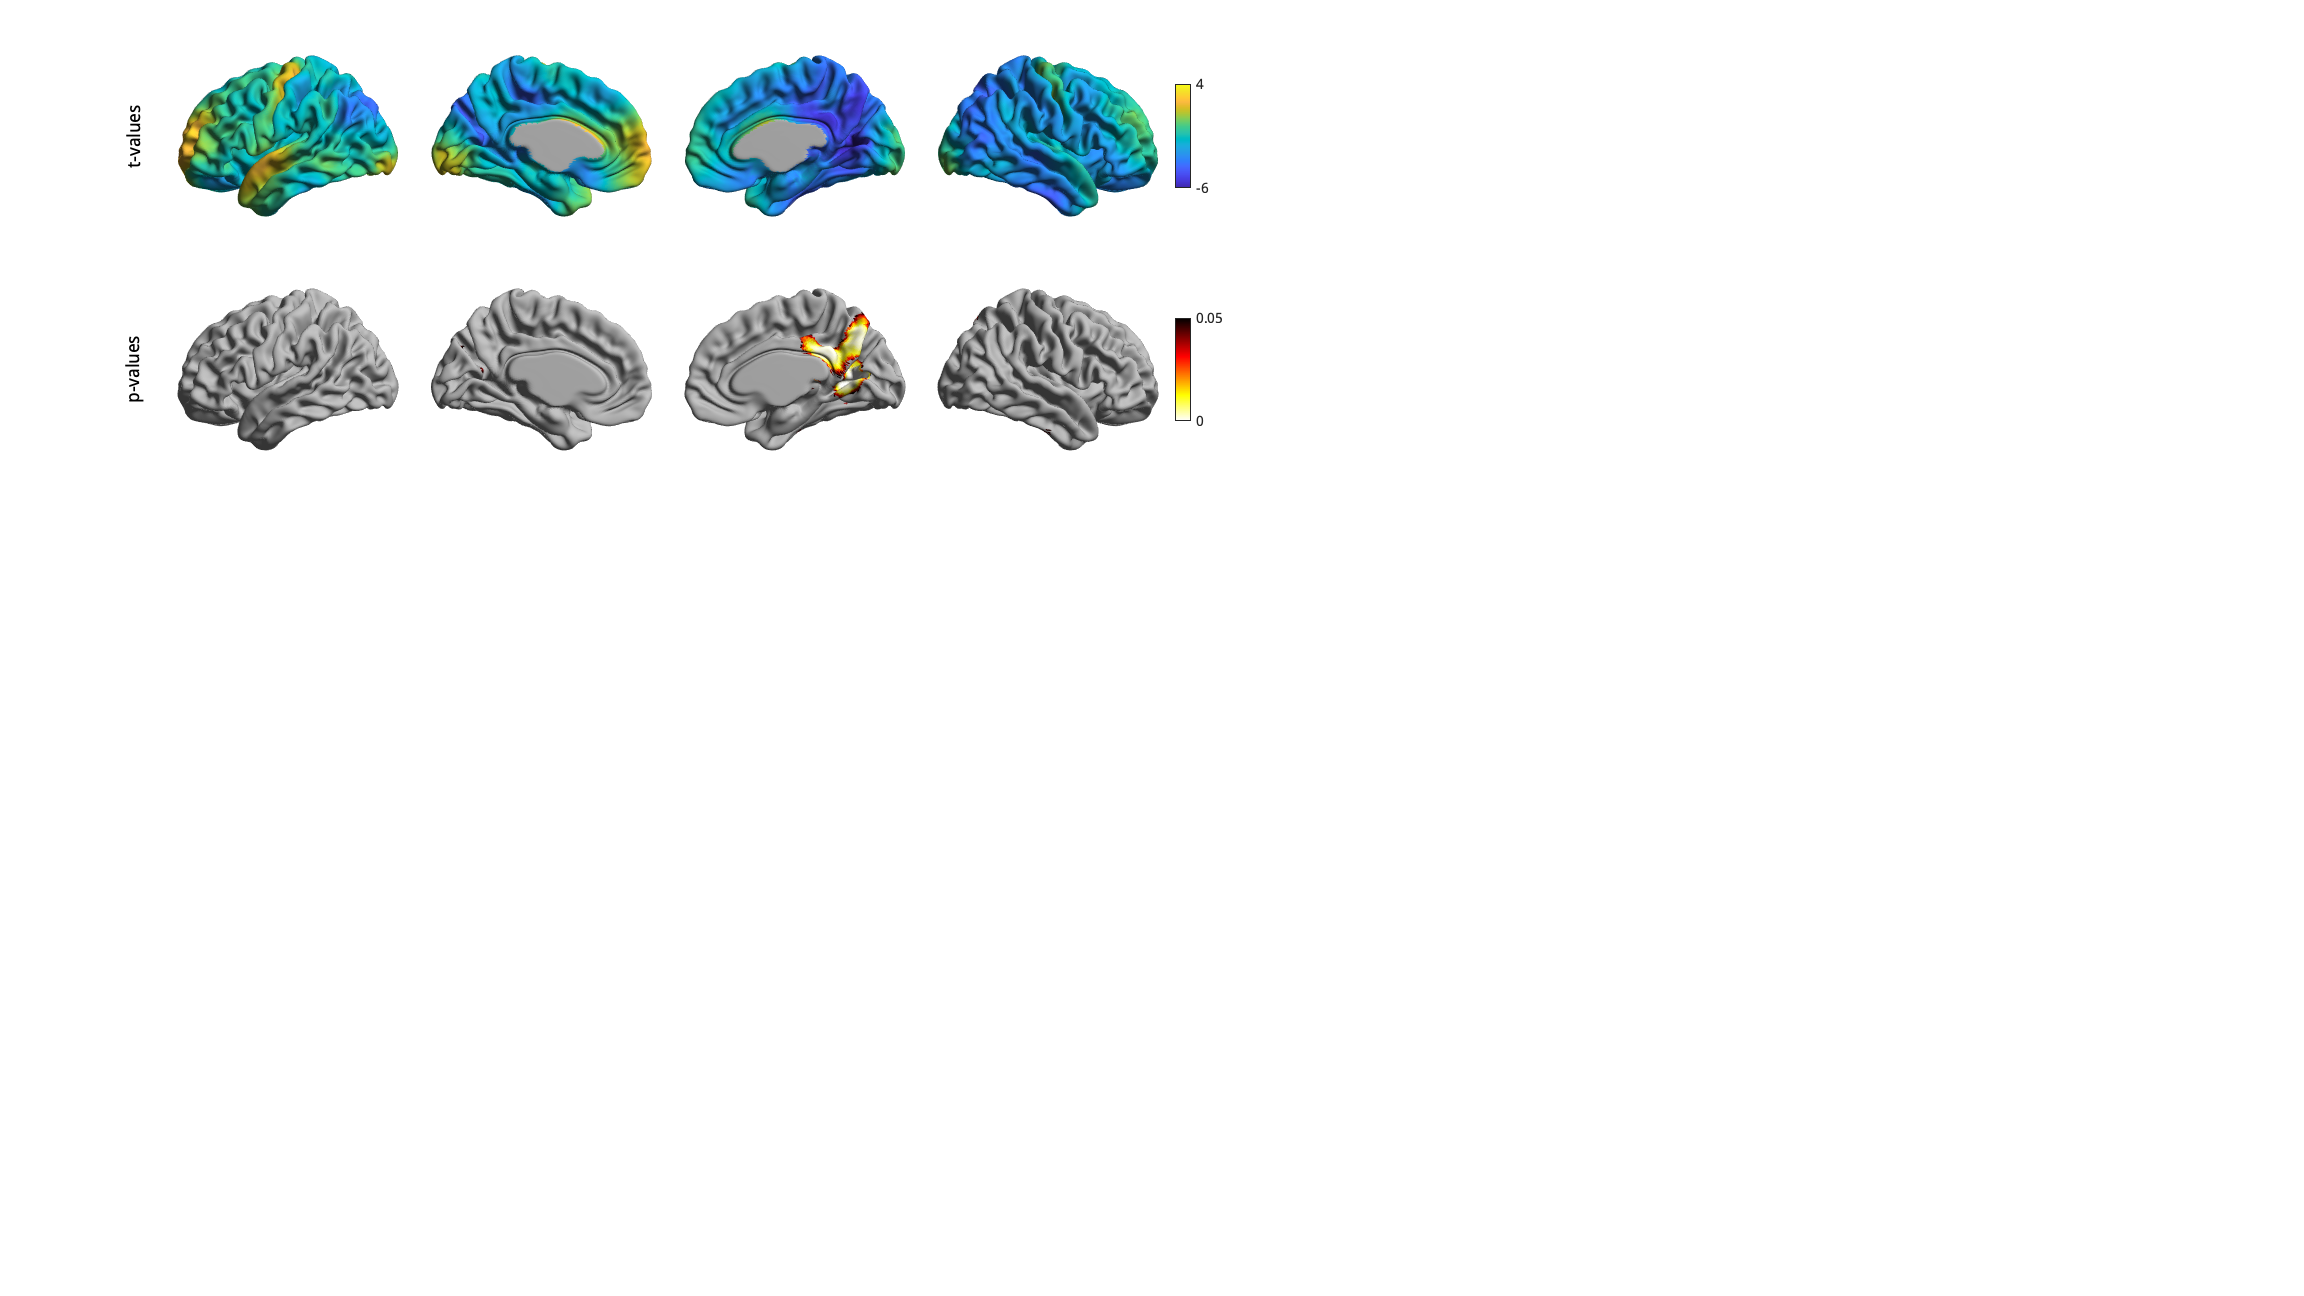

to_plot1 = [BrainStatModel.t', BrainStatModel.P.pval.P'];
to_plot1(~mask,:) = inf;

plot1 = plot_hemispheres(...
    to_plot1,  ...
    {surf_left, surf_right}, ...
    'labeltext', {'t-values', 'p-values'} ...
);

plot1.colormaps({[parula; .7 .7 .7], [flipud(hot); .7 .7 .7]})
plot1.colorlimits([-6, 4; 0, 0.05])

By default BrainStat uses a two-tailed test. If you want to get a one-tailed test, simply specify it in the SLM model initialization with `'two_tailed', false`. Note that the one-tailed test will test for positive t-values. If you want to test for negative t-values, simply invert the contrast. We may hypothesize based on prior research that cortical thickness decreases with age, so we could specify this as follows. Note the minus in front of `contrast_age` to test for decreasing thickness with age.

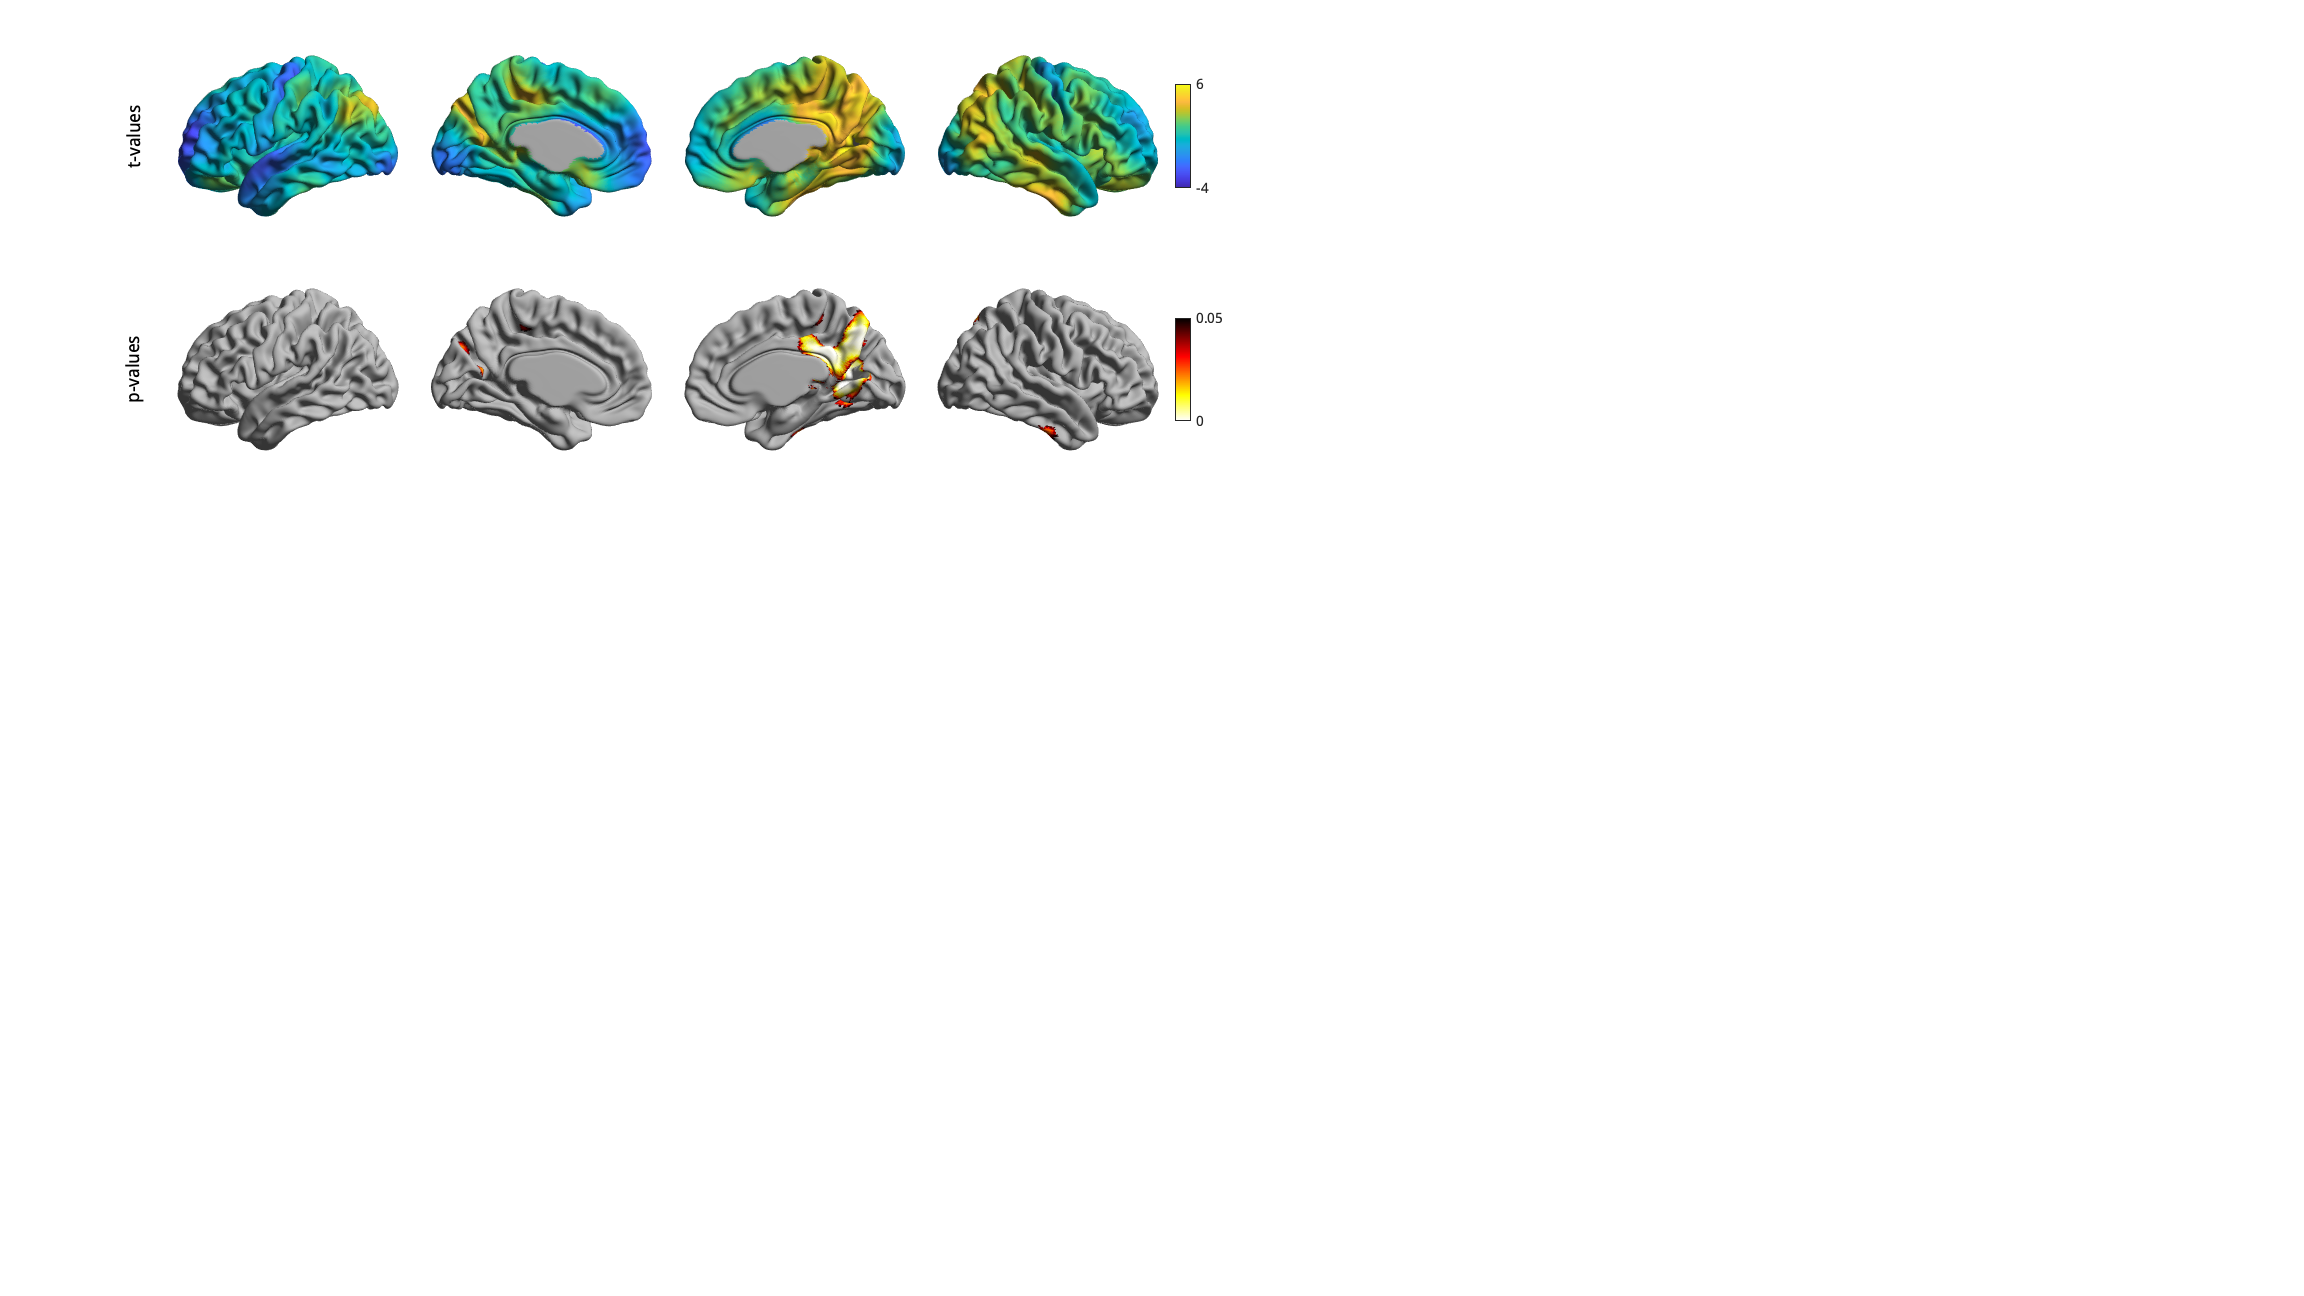

BrainStatModel_onetailed = SLM(...
    model, ...
    -contrast_age, ...
    'correction', 'rft', ...
    'surf', {surf_left, surf_right}, ...
    'mask', mask, ...
    'two_tailed', false ...
);
BrainStatModel_onetailed.fit(cortical_thickness);

to_plot2 = [BrainStatModel_onetailed.t', BrainStatModel_onetailed.P.pval.P'];
to_plot2(~mask,:) = inf;

plot2 = plot_hemispheres(...
    to_plot2,  ...
    {surf_left, surf_right}, ...
    'labeltext', {'t-values', 'p-values'} ...
);

plot2.colormaps({[parula; .7 .7 .7], [flipud(hot); .7 .7 .7]})
plot2.colorlimits([-4, 6; 0, 0.05])

Now, imagine that instead of using a fixed effects model, you would prefer a mixed effects model wherein the scanning site is a random variable. This is simple to set up. All you need to do is initialize the site term with the `MixedEffect` class, all other code remains identical.

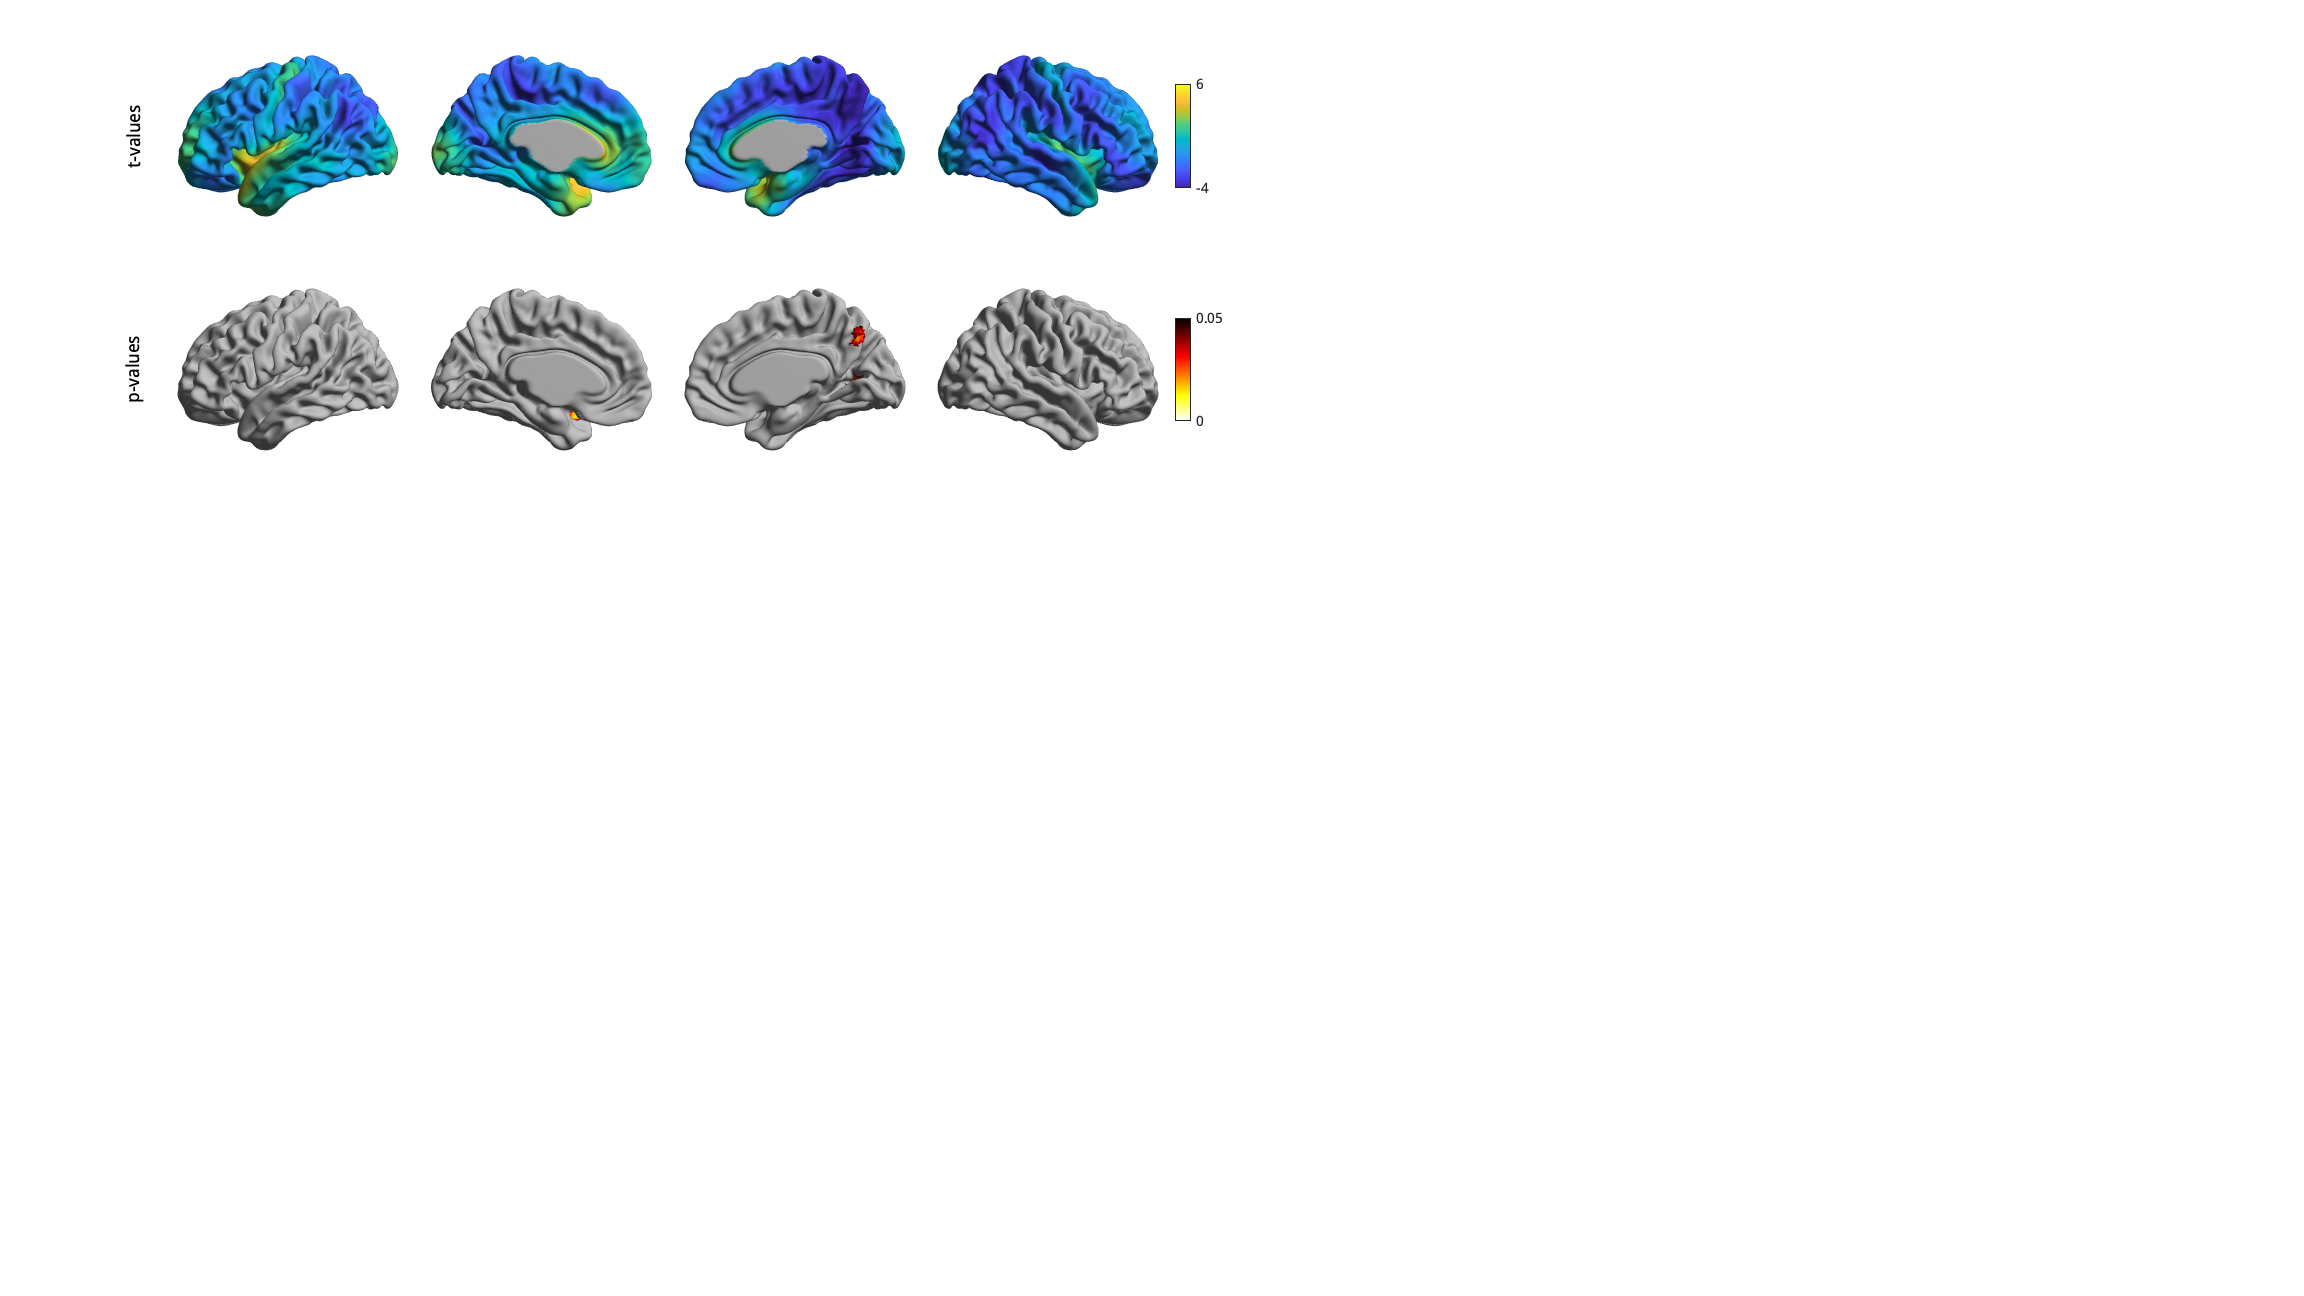

random_site = MixedEffect(demographics.SITE_ID);
model_random = term_age + term_patient + random_site;
BrainStatModel_random = SLM(model_random, contrast_age, ...
    'surf', {surf_left, surf_right}, 'mask', mask, 'correction', 'rft');
BrainStatModel_random.fit(cortical_thickness)

to_plot3 = [BrainStatModel_random.t', BrainStatModel_random.P.pval.P'];
to_plot3(~mask,:) = inf;

plot3 = plot_hemispheres(...
    to_plot3,  ...
    {surf_left, surf_right}, ...
    'labeltext', {'t-values', 'p-values'} ...
);

plot3.colormaps({[parula; .7 .7 .7], [flipud(hot); .7 .7 .7]})
plot3.colorlimits([-4, 6; 0, 0.05])

It appears that, after correction for site as a random variable, the significant results are far more localized. That concludes the basic usage of the BrainStat for statistical models. In the next tutorial we'll show you how to use the context decoding module.